# Data analysis of localization confidence

- Compares confidence between unimodal and bimodal conditions

clear; clc; close all;
sub_slc     = 4;
ses_slc     = 1:2;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(pwd, mfilename);
addpath(genpath(fullfile(project_dir,'func')))
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[bi_resp, bi_conf, bi_err, ExpInfo] = org_data(sub_slc,ses_slc,'biLoc');
[uni_resp, uni_conf, uni_err, uniExpInfo, ~, ScreenInfo] = org_data(sub_slc,[],'uniLoc'); % condition (A,V1,V2) x loc (4) x rep

%% analyze real data
[mean_conf, std_mean_conf, uni_pconf, abs_diff,...
    mean_ve, std_ve, raw_diff] = analyze_data(sub_slc, ses_slc);

% conditions
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
cue_label   = {'Post-cue: A','Post-cue: V'};
num_cue     = numel(cue_label);
visReliIdx  = ExpInfo.visReliIdx;
deg_per_px  = rad2deg(atan(170 / 2 / ExpInfo.sittingDistance)) .* 2 / ScreenInfo.xaxis;cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
num_rel     = numel(rel_label);
aud_locs    = ExpInfo.speakerLocVA(ExpInfo.audIdx);
remapped_vis_locs = ExpInfo.targetPixel .* deg_per_px;
num_rep     = ExpInfo.nRep;


## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255; % gray
%     251, 154, 153]./255; % light red


## Sanity check: localization response

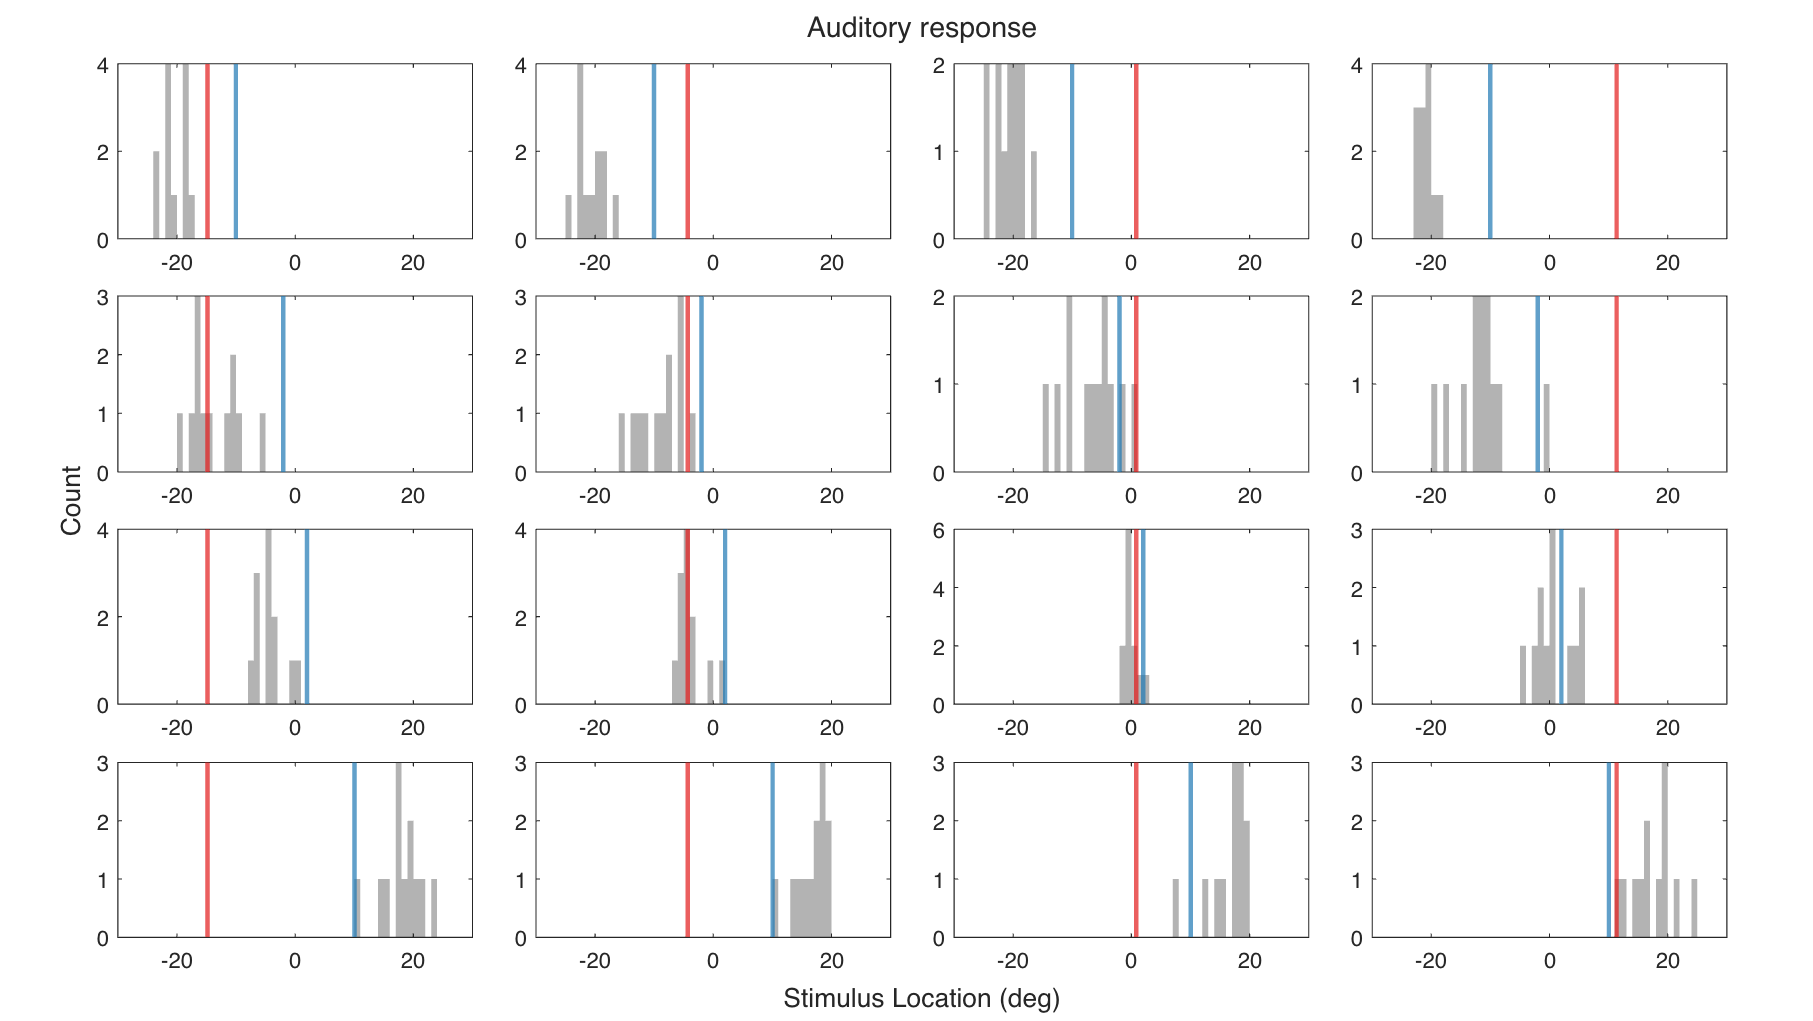

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
        curr_resp = squeeze(bi_resp(a, v, 1, 1, :));
        nexttile
        h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
        h.FaceColor = repmat(0.5, 1, 3);
        h.EdgeColor = 'none';

        xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
        xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

        xlim([-30, 30])
    end
end

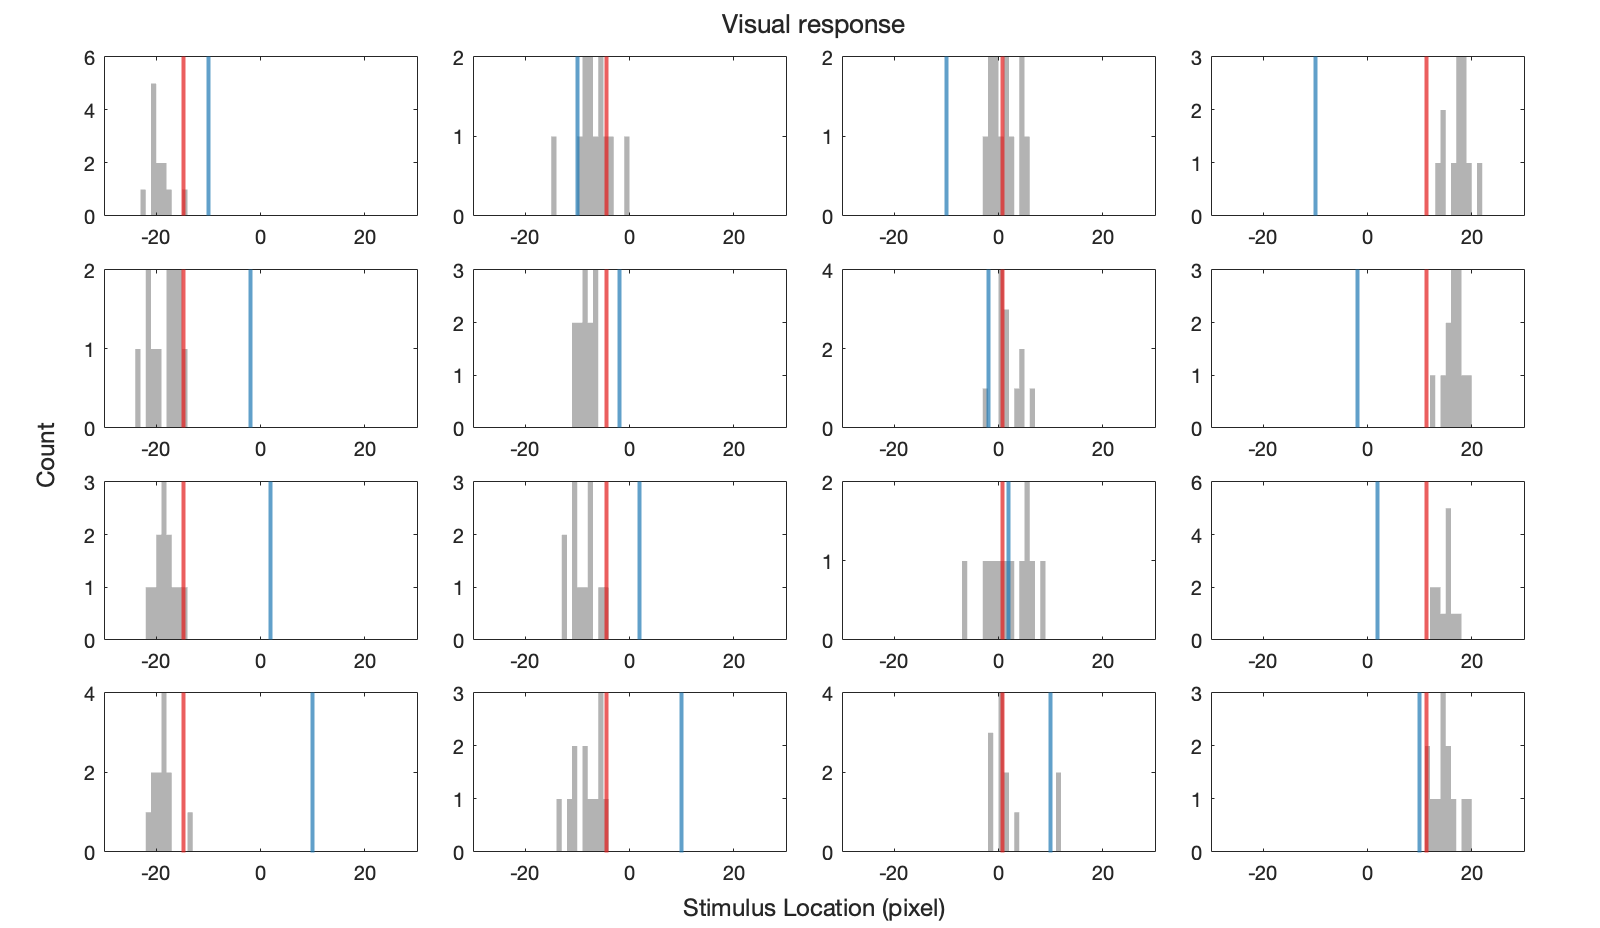



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
        curr_resp = squeeze(bi_resp(a, v, 2, 2, :));
        nexttile
        h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
        h.FaceColor = repmat(0.5, 1, 3);
        h.EdgeColor = 'none';

        xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
        xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

        xlim([-30, 30])
    end
end

## Is confidence modulated by cue discrepancy and cue reliability?

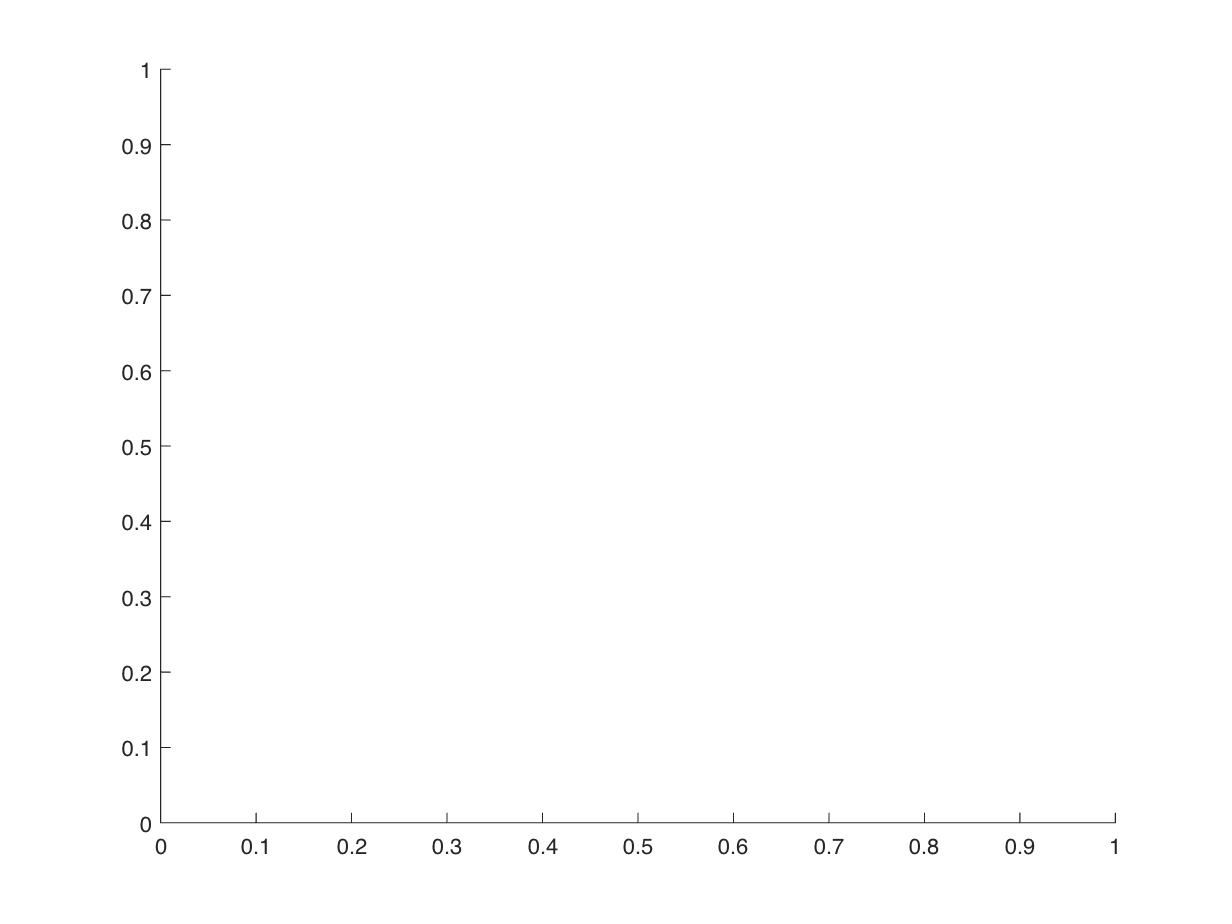

figure; hold on

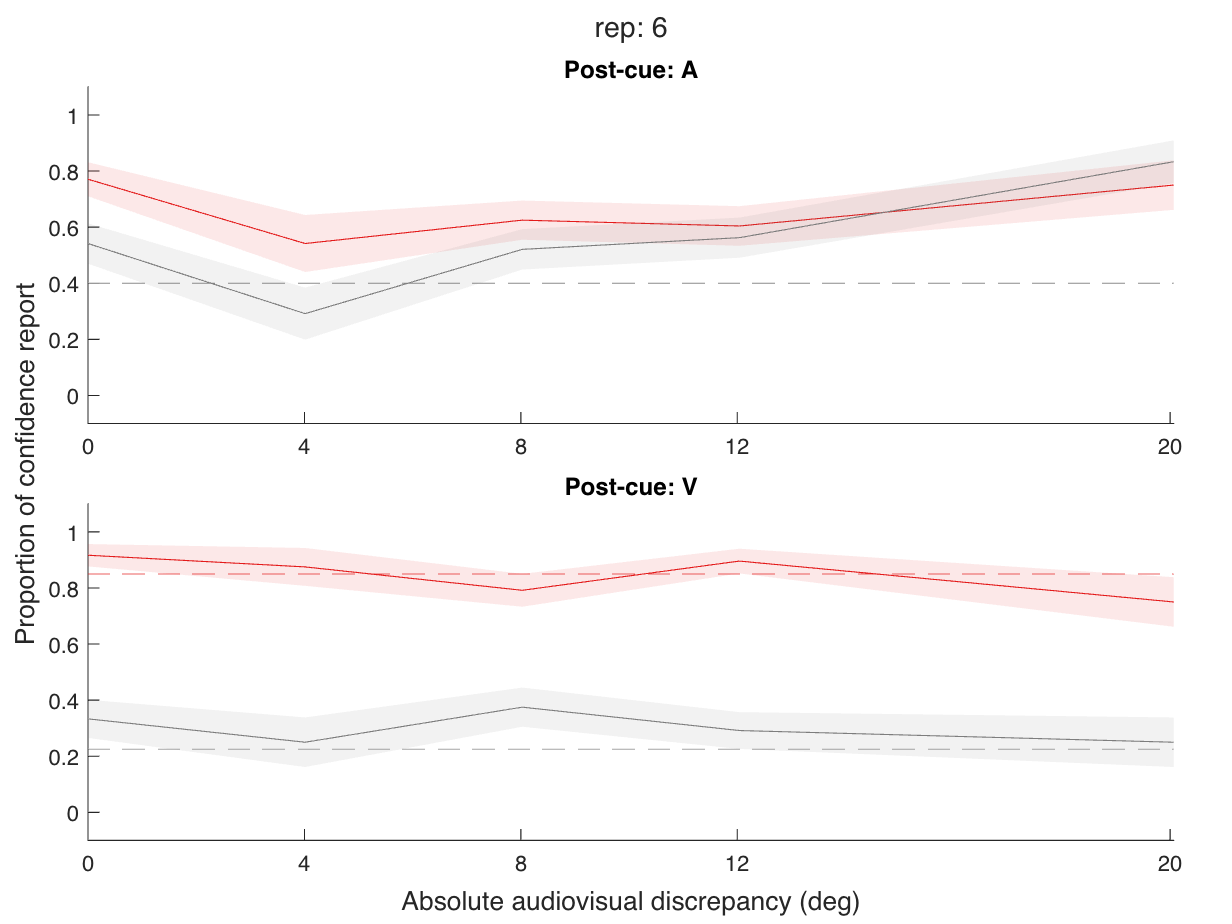



figure; hold on
t = tiledlayout(2, 1);
title(t,sprintf('rep: %i', num_rep))
xlabel(t, 'Absolute audiovisual discrepancy (deg)');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:num_cue

    nexttile
    title(cue_label{cue})
    hold on
    xticks(round(abs_diff))
    ylim([-0.1, 1.1])
    xlim([min(abs_diff), max(abs_diff)])

    for rel = 1:num_rel

        % plot data
        %         plot(abs_diff, squeeze(mean_conf(:, cue, rel)), 'o-', 'Color',clt(rel+1,:));
        plot(abs_diff, mean_conf(:, cue, rel), 'Color',clt(rel+1,:))
        patch([abs_diff, fliplr(abs_diff)], ...
            [mean_conf(:, cue, rel)' - std_mean_conf(:, cue, rel)', ...
            fliplr(mean_conf(:, cue, rel)' + std_mean_conf(:, cue, rel)')], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1)

        % plot unimodal p_confidence
        if cue == 1
            yline(uni_pconf(1),'--','Color',repmat(0.5,1,3))
        else
            yline(uni_pconf(rel+1),'--','Color',clt(rel+1,:))
        end

    end

end

## Ventriloquist effect

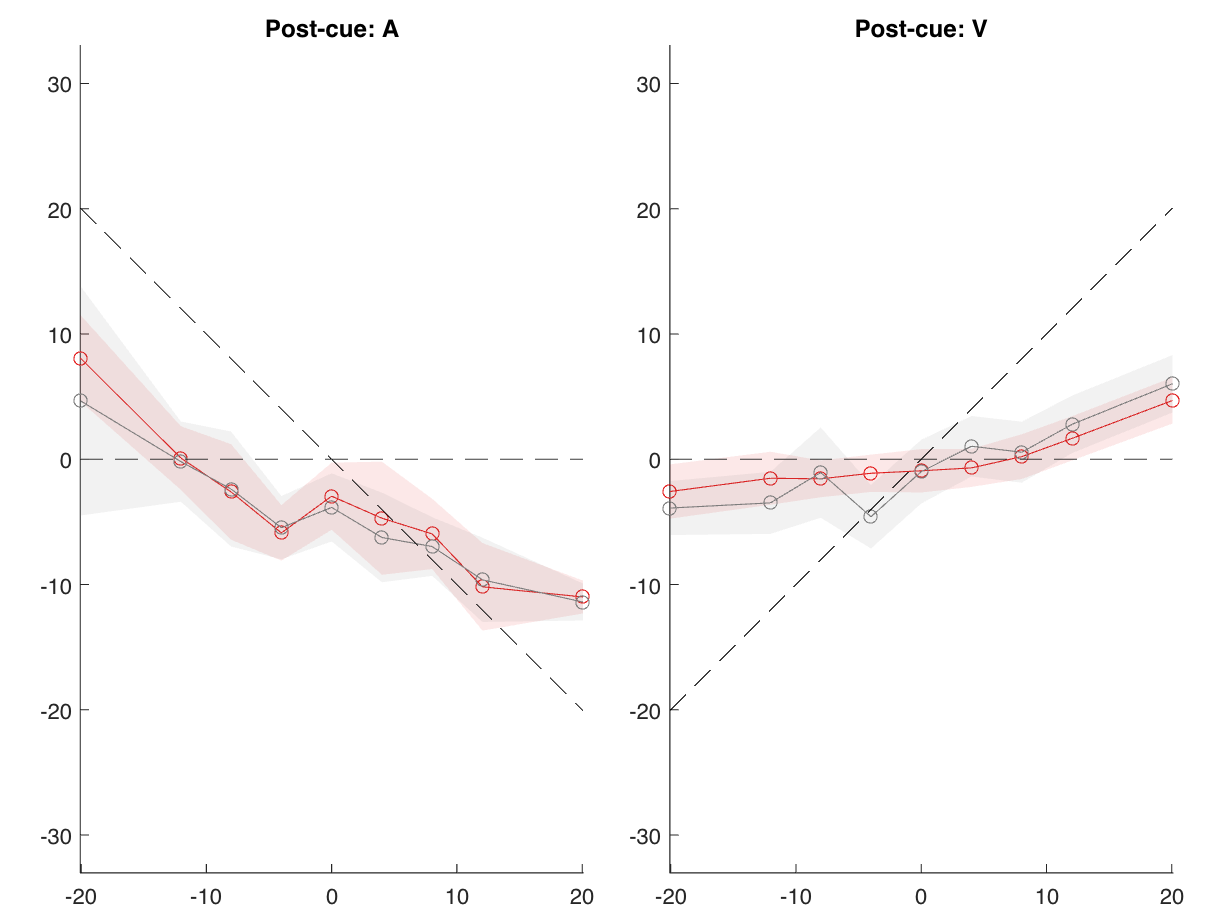

figure
t = tiledlayout(1,2);
% xlabel(t, 'Audiovisual discrepancy (pixel)');
% ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    axis equal
    hold on
    for rel = 1:numel(visReliIdx)

        plot(raw_diff, mean_ve(:, cue, rel),'-o', 'Color',clt(rel+1,:));
        patch([raw_diff, fliplr(raw_diff)], ...
            [mean_ve(:, cue, rel)' - std_ve(:,cue, rel)', ...
            fliplr(mean_ve(:, cue, rel)' + std_ve(:,cue, rel)')],...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off');

        yline(0,'--')

        if cue == 1
            plot(raw_diff, -raw_diff,'k--')
        else
            plot(raw_diff, raw_diff,'k--')
        end
    end
end